clear all; clc; 

load("Data/vanvikan/imu_measurements_1_2.mat");

fs = 250; 

run_resample = false;
resample_rate = 0.4;

signalx = imuData.acceleration(1,:);
signaly = imuData.acceleration(2,:);
signalz = imuData.acceleration(3,:) - 9.81;

%% Resample signal

if run_resample == true
    signalx = resample(signalx,resample_rate*fs,fs);
    signaly = resample(signaly,resample_rate*fs,fs);
    signalz = resample(signalz,resample_rate*fs,fs);
    fs = fs*resample_rate; 
end

dt = 1 / fs;

N = length(signalx);
t = 0:dt:(N-1)*dt;

last_n_minutes = 1;
start_idx = last_n_minutes * 250 * 60;
signal_interval = [N-start_idx:N];

%% Trunc signals

signalx = signalx(signal_interval);
signaly = signaly(signal_interval);
signalz = signalz(signal_interval);
t = t(signal_interval);

interval_in_s = [(N-start_idx)/fs,N/fs];

%% Plot raw signal

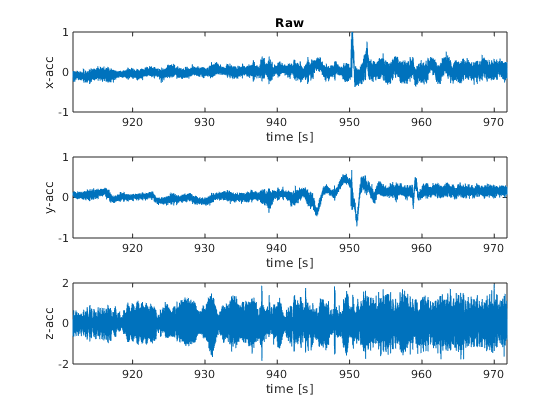

clf;
subplot(311); 
plot_nice(t, signalx, interval_in_s, [-1,1], "time [s]","x-acc");
subplot(312);
plot_nice(t, signaly, interval_in_s, [-1,1], "time [s]","y-acc");
subplot(313);
plot_nice(t, signalz, interval_in_s, [-2,2], "time [s]","z-acc");

currentFigure = gcf;
title(currentFigure.Children(end), "Raw");

%% Lowpass filter

cutoff_f = 5;

signal_lp_x = lowpass(signalx, cutoff_f, fs);
signal_lp_y = lowpass(signaly, cutoff_f, fs);
signal_lp_z = lowpass(signalz, cutoff_f, fs);

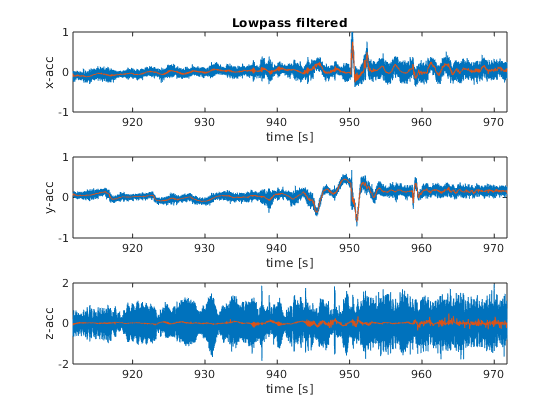

clf;
subplot(311); 
plot_nice(t, signalx, interval_in_s, [-1,1], "time [s]","x-acc"); hold on;
plot_nice(t, signal_lp_x, interval_in_s, [-1,1], "time [s]","x-acc");
subplot(312);
plot_nice(t, signaly, interval_in_s, [-1,1], "time [s]","y-acc"); hold on;
plot_nice(t, signal_lp_y, interval_in_s, [-1,1], "time [s]","y-acc");
subplot(313);
plot_nice(t, signalz, interval_in_s, [-2,2], "time [s]","z-acc"); hold on;
plot_nice(t, signal_lp_z, interval_in_s, [-2,2], "time [s]","z-acc");

currentFigure = gcf;
title(currentFigure.Children(end), "Lowpass filtered");

%% CWT

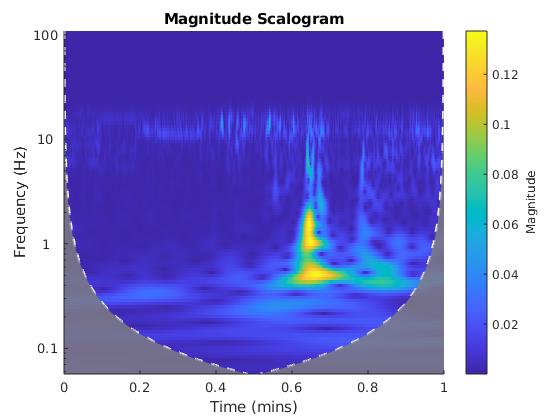

clf;
subplot(311); 
cwt(signal_lp_x, 'morse', fs);

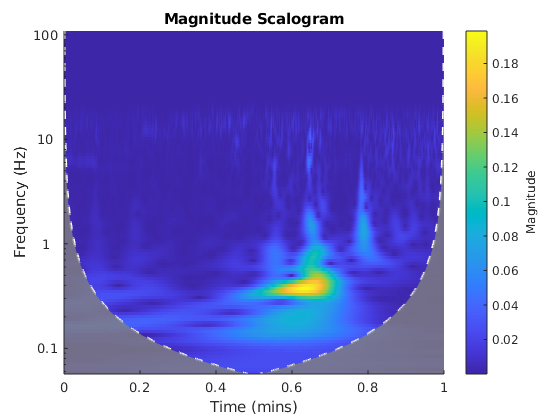

subplot(312);
cwt(signal_lp_y, 'morse', fs);

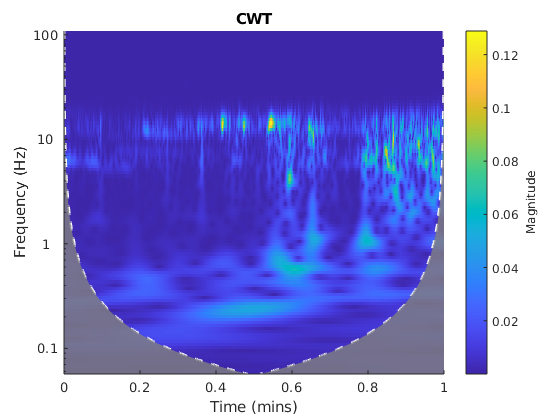

subplot(313);
cwt(signal_lp_z, 'morse', fs);

currentFigure = gcf;
title(currentFigure.Children(end), "CWT");

%% STFT

wmin = 1250;
f_max = cutoff_f;

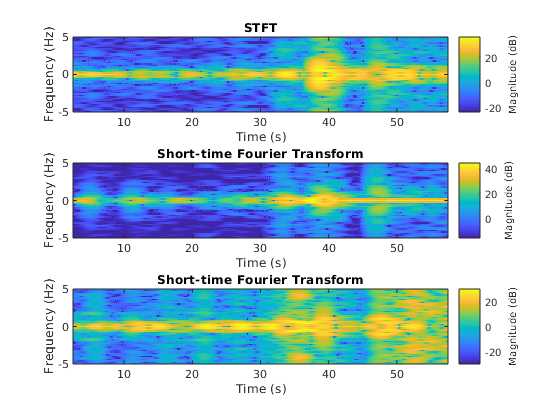

clf;
subplot(311); 
stft(signal_lp_x,fs,'Window',kaiser(wmin,5),'OverlapLength',wmin-1,'FFTLength',wmin); ylim([-f_max, f_max])
subplot(312);
stft(signal_lp_y,fs,'Window',kaiser(wmin,5),'OverlapLength',wmin-1,'FFTLength',wmin); ylim([-f_max, f_max])
subplot(313);
stft(signal_lp_z,fs,'Window',kaiser(wmin,5),'OverlapLength',wmin-1,'FFTLength',wmin); ylim([-f_max, f_max])

currentFigure = gcf;
title(currentFigure.Children(end), "STFT");

%% Instantaneous frequncy

hilbx = hilbert(signal_lp_x);
instfrqx = fs/(2*pi)*diff(unwrap(angle(hilbx)));
hilby = hilbert(signal_lp_y);
instfrqy = fs/(2*pi)*diff(unwrap(angle(hilby)));
hilbz = hilbert(signal_lp_z);
instfrqz = fs/(2*pi)*diff(unwrap(angle(hilbz)));

ang_diff_max = 100;

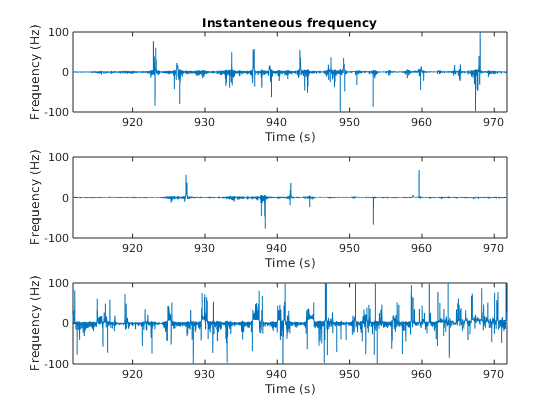

clf;
subplot(311); 
plot_nice(t(2:end), instfrqx, interval_in_s, [-ang_diff_max,ang_diff_max], "Time (s)", "Frequency (Hz)")
subplot(312); 
plot_nice(t(2:end), instfrqy, interval_in_s, [-ang_diff_max,ang_diff_max], "Time (s)", "Frequency (Hz)")
subplot(313); 
plot_nice(t(2:end), instfrqz, interval_in_s, [-ang_diff_max,ang_diff_max], "Time (s)", "Frequency (Hz)")


currentFigure = gcf;
title(currentFigure.Children(end), "Instanteneous frequency");

%% Too time consuming
% clf;
% subplot(311);
% wvd(signal_lp_x,fs);
% subplot(312);
% wvd(signal_lp_y,fs);
% subplot(313);
% wvd(signal_lp_z,fs);
% 
% currentFigure = gcf;
% title(currentFigure.Children(end), "Wigner-Ville Transform");

%% EMD and HT

sift_num = 100;

imfx = emd(signal_lp_x,'Display',1, 'Interpolation','spline', 'SiftMaxIterations',sift_num);

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |      0.04575   |  SiftMaxRelativeTolerance
      2      |        2     |      0.11867   |  SiftMaxRelativeTolerance
      3      |        4     |      0.14977   |  SiftMaxRelativeTolerance
      4      |        2     |     0.013155   |  SiftMaxRelativeTolerance
      5      |        2     |     0.016945   |  SiftMaxRelativeTolerance
      6      |        2     |      0.19764   |  SiftMaxRelativeTolerance
      7      |        3     |     0.004032   |  SiftMaxRelativeTolerance
The decomposition stopped because the number of extrema of the residual signal is less than 'MaxNumExtrema'.


imfy = emd(signal_lp_y,'Display',1, 'Interpolation','spline', 'SiftMaxIterations',sift_num);

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        3     |     0.049028   |  SiftMaxRelativeTolerance
      2      |        3     |     0.076465   |  SiftMaxRelativeTolerance
      3      |        3     |     0.052179   |  SiftMaxRelativeTolerance
      4      |        2     |    0.0064044   |  SiftMaxRelativeTolerance
      5      |        2     |      0.12068   |  SiftMaxRelativeTolerance
      6      |        2     |      0.03502   |  SiftMaxRelativeTolerance
      7      |        2     |    0.0012572   |  SiftMaxRelativeTolerance
The decomposition stopped because the number of extrema of the residual signal is less than 'MaxNumExtrema'.


imfz = emd(signal_lp_z,'Display',1, 'Interpolation','spline', 'SiftMaxIterations',sift_num);

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.046918   |  SiftMaxRelativeTolerance
      2      |        2     |     0.035979   |  SiftMaxRelativeTolerance
      3      |        3     |     0.029413   |  SiftMaxRelativeTolerance
      4      |        2     |      0.11086   |  SiftMaxRelativeTolerance
      5      |        2     |    0.0081041   |  SiftMaxRelativeTolerance
      6      |        3     |     0.017761   |  SiftMaxRelativeTolerance
      7      |        2     |     0.015139   |  SiftMaxRelativeTolerance
      8      |        3     |     0.022643   |  SiftMaxRelativeTolerance
      9      |        2     |    0.0063323   |  SiftMaxRelativeTolerance
The decomposition stopped because the number of extrema of the residual signal is less than 'MaxNumExtrema'.


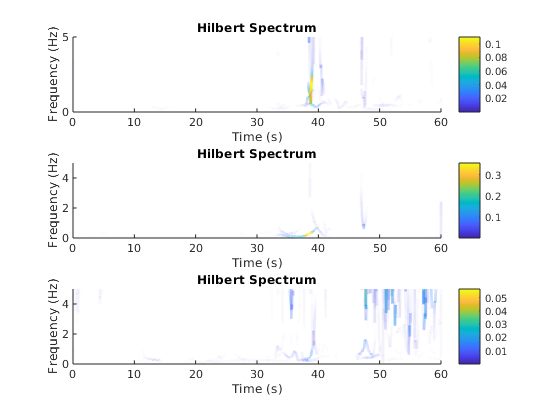

subplot(311);
hht(imfx,fs,'FrequencyLimits',[0 f_max]); set(gca,'Color','w')
subplot(312);
hht(imfy,fs,'FrequencyLimits',[0 f_max]); set(gca,'Color','w')
subplot(313);
hht(imfz,fs,'FrequencyLimits',[0 f_max]); set(gca,'Color','w')